# Лабораторна робота No6

# Блокова обробка. Реалізація алгоритму JPEG

clear; close all; clc;

## **1. Завантаження чорнобілих та кольорових зображень**

I1 = imread('fabric.png');
I2 = imread('cameraman.tif');

## 2. Перетворення кольорових в чорнобілі та вивід зображень

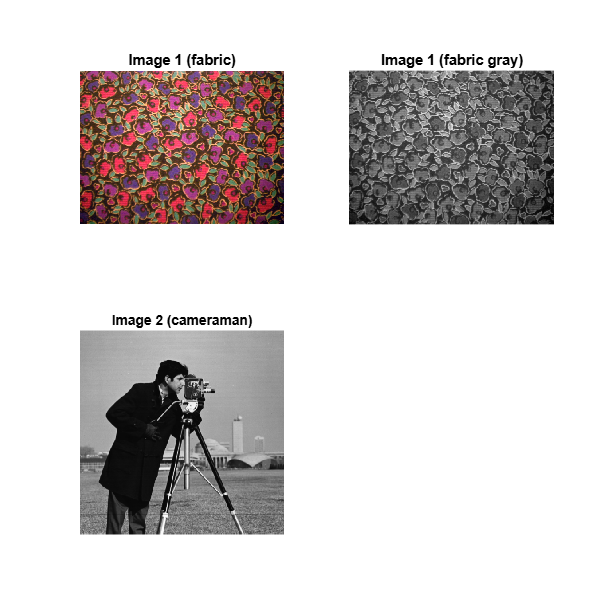

I1G = im2double(rgb2gray(I1));
I2G = im2double(I2);

figure;
subplot(2,2,1), imshow(I1), title('Image 1 (fabric)');
subplot(2,2,2), imshow(I1G), title('Image 1 (fabric gray)');
subplot(2,2,3), imshow(I2), title('Image 2 (cameraman)');
truesize;

## 3. Поблочне ДКП(DCT)

% розмір блока та матриця коефіцієнтів ДКП
blockSize = 8;
T = dctmtx(blockSize);

% процедура
dct = @(block_struct) T * block_struct.data * T';

% поблочна обробка зображень
B1 = blockproc(I1G, [blockSize blockSize], dct);
B2 = blockproc(I2G, [blockSize blockSize], dct);

## 4. Відображення отриманих результатів перетворень зображень використовуючи логарифмічний маштаб

**Поясніть вигляд отриманого зображення. **

логарифмічний масштаб дає змогу краще побачити слабкі (низькоенергетичні) коефіцієнти. Без логарифма більшість значень зливаються через перевагу низьких частот.

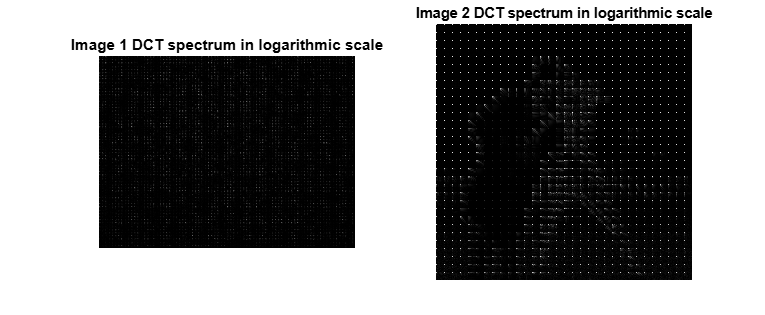

figure;
subplot(1,2,1), imshow(log(abs(B1) + 1), []), title('Image 1 DCT spectrum in logarithmic scale');
subplot(1,2,2), imshow(log(abs(B2) + 1), []), title('Image 2 DCT spectrum in logarithmic scale');
truesize;

## 5. Відновлення зображення

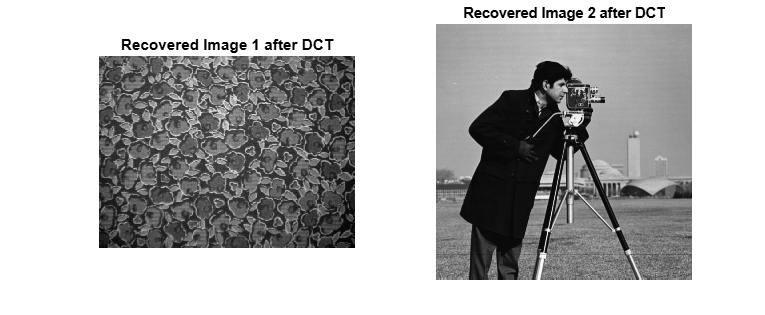

invdct = @(block_struct) T' * block_struct.data * T;

I1_recovery = blockproc(B1, [blockSize blockSize], invdct);
I2_recovery = blockproc(B2, [blockSize blockSize], invdct);

figure;
subplot(1,2,1), imshow(I1_recovery), title('Recovered Image 1 after DCT');
subplot(1,2,2), imshow(I2_recovery), title('Recovered Image 2 after DCT');
truesize;

## 6. Квантування результатів ДКП для різних значень кроку квантування N.

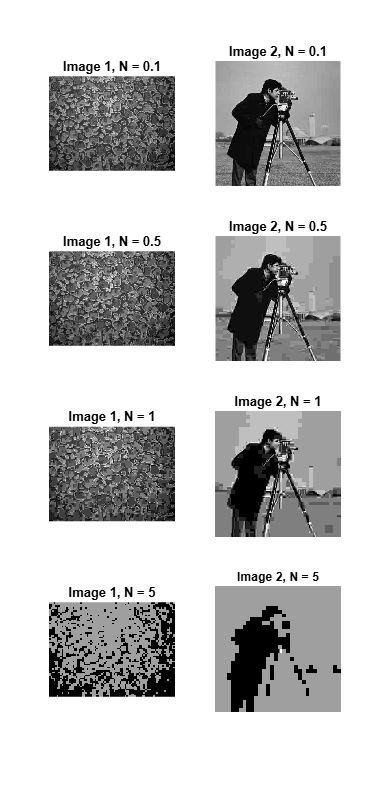

N_values = [0.1, 0.5, 1, 5];
figure;
for i = 1:length(N_values)
    N = N_values(i);

    % Квантування та відновлення для B1
    B1q = N * round(B1 / N);
    I1q = blockproc(B1q, [blockSize blockSize], invdct);

    % Квантування та відновлення для B2
    B2q = N * round(B2 / N);
    I2q = blockproc(B2q, [blockSize blockSize], invdct);

    % зліва — B1, справа — B2
    subplot(length(N_values), 2, (i-1)*2 + 1);
    imshow(I1q);
    title(['Image 1, N = ' num2str(N)]);

    subplot(length(N_values), 2, (i-1)*2 + 2);
    imshow(I2q);
    title(['Image 2, N = ' num2str(N)]);
end
truesize;

## 7. Квантування коефіцієнтів ДКП, використовуючи маску та процедуру

mask = [
    1 1 1 1 0 0 0 0;
    1 1 1 0 0 0 0 0;
    1 1 0 0 0 0 0 0;
    1 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0
];

% застосування маски до кожного блока
B1m = blockproc(B1, [blockSize blockSize], @(block_struct) mask .* block_struct.data);
B2m = blockproc(B2, [blockSize blockSize], @(block_struct) mask .* block_struct.data);

## 8. Відновлення зображення

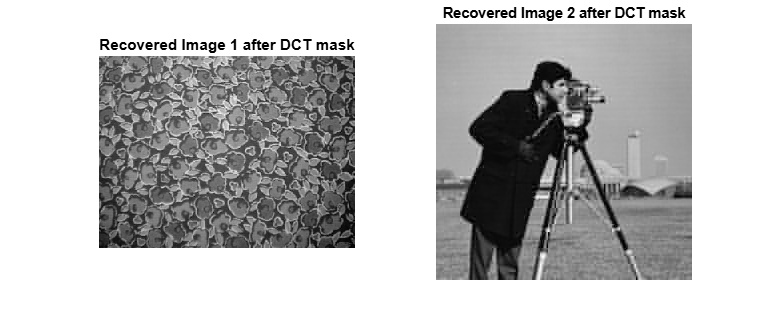

% зворотне перетворення ДКП
I1_recovery2 = blockproc(B1m, [blockSize blockSize], invdct);
I2_recovery2 = blockproc(B2m, [blockSize blockSize], invdct);


figure;
subplot(1,2,1), imshow(log(abs(I1_recovery2) + 1), []), title('Recovered Image 1 after DCT mask');
subplot(1,2,2), imshow(log(abs(I2_recovery2) + 1), []), title('Recovered Image 2 after DCT mask');
truesize;

## 9. Пояснення результату

Квантування зменшує точність коефіцієнтів ДКП, особливо для високочастотних (які менш помітні людському оку), що дає змогу:

- зменшити обсяг даних;

- здійснити стиснення з втратами (як у JPEG);

- зберегти візуальну якість при помітному зменшенні розміру.